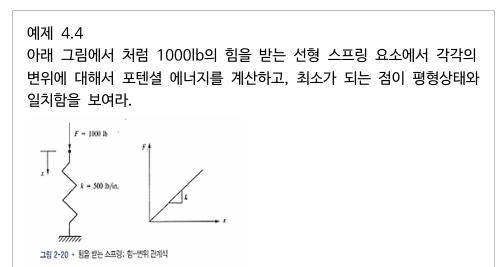

**예제 4.4: 스프링 요소의 포텐셜 에너지 최소화문제 상황**

- 그림에서 스프링에 1000 lb의 외부 힘이 작용하고 있습니다.

- 스프링의 변위에 따른 포텐셜 에너지를 계산하고, 이 포텐셜 에너지를 최소화하여 평형 상태를 찾는 것이 목표입니다.

**포텐셜 에너지 계산**

- **전체 포텐셜 에너지 **$\pi_p$**:**

- 스프링의 전체 포텐셜 에너지는 변형 에너지 $U$와 외부 힘에 의한 포텐셜 에너지 $\Omega$의 합으로 표현됩니다.


$$\pi_p = U + \Omega$$


- **변형 에너지 **$U$**:**

- 변형 에너지는 스프링이 변형될 때 내부에 저장되는 에너지입니다.

- 식으로 표현하면: 


$$U = \frac{1}{2} k x^2$$


- 여기서 $k$는 스프링 상수이고, $x$는 변위입니다.

- **외부 힘에 의한 포텐셜 에너지 **$\Omega$**:**

- 외부 힘이 스프링에 작용하여 변형시킬 때 발생하는 포텐셜 에너지는: 


$$\Omega = -Fx$$


- 여기서 $F$는 외부에서 가해지는 힘입니다.

**전체 포텐셜 에너지 수식**

- 스프링 시스템의 전체 포텐셜 에너지는 다음과 같이 나타낼 수 있습니다:


$$\pi_p = \frac{1}{2} k x^2 - Fx$$


**포텐셜 에너지 최소화**

- **최소화 조건:**

- 평형 상태를 찾기 위해 전체 포텐셜 에너지를 변위 $x$에 대해 편미분하여 최소화 조건을 찾습니다.

- 최소화 조건은: 


$$\frac{\partial \pi_p}{\partial x} = 0\$$


- 위 식을 구하면: 


$$\frac{\partial \pi_p}{\partial x} = kx - F = 0$$


- **평형 상태:**

- 이 식을 $x$에 대해 풀면: 


$$kx = F \quad \Rightarrow \quad x = \frac{F}{k}$$


- 이는 스프링의 변위가$x = \frac{F}{k}$일 때 시스템이 평형 상태에 있음을 나타냅니다.

**예제 수치 대입**

- 예제에서 $x = 2.00 in$으로 가정하고 주어진 수식을 대입하면:

- 스프링 상수$k = 500 lb/in$

- 외부 힘 $F = 1000 lb$

- 전체 포텐셜 에너지 $\pi_p: \pi_p = \frac{1}{2} (500) x^2 - 1000 x$

- $x = 2.00$일 때 포텐셜 에너지: $\pi_p = \frac{1}{2} \times 500 \times (2)^2 - 1000 \times 2 = 250 \times 4 - 2000 = 1000 - 2000 = -1000 \text{ lb-in}$

**결과**

- 주어진 수식에서 $\pi_p$를 최소화하는 변위 $ x$를 찾으면, 이는 외부 힘과 스프링 상수의 비율에 의해 결정됩니다.

- $x = \frac{F}{k}$를 대입하여 평형 상태에서의 변위를 결정할 수 있습니다.

- 이 결과는 힘이 스프링에 저장되는 에너지가 최소가 되는 지점이 시스템의 평형 상태와 일치함을 보여줍니다.

**결론**

- **포텐셜 에너지의 최소화:** 포텐셜 에너지를 최소화함으로써 스프링 시스템의 평형 상태를 찾을 수 있습니다. 이는 변위에 대한 편미분을 통해 얻은 결과입니다.

- **평형 상태의 의미:** 스프링의 평형 상태에서 포텐셜 에너지는 최소가 되며, 이 지점에서 외부 힘과 스프링의 복원력이 균형을 이루게 됩니다.

- **실제 응용:** 이러한 개념은 스프링 시스템뿐만 아니라 다양한 물리 시스템에서 안정된 평형 상태를 찾는 데 사용됩니다.

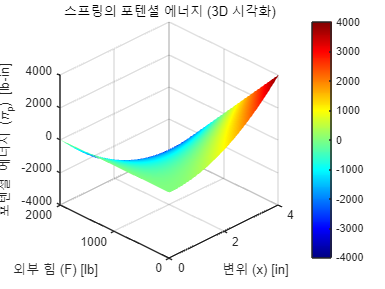

% 스프링 시스템의 포텐셜 에너지 최소화 예제
% 스프링 상수 (k), 외부 힘 (F), 변위 (x)를 정의

% 스프링 상수 (k) 고정
k = 500; % lb/in

% 외부 힘 (F)의 범위 설정
F_values = linspace(0, 2000, 50); % 외부 힘 범위
x_values = linspace(0, 4, 50); % 변위 범위
[F, x] = meshgrid(F_values, x_values); % 변위 x와 외부 힘 F의 그리드 생성

% 포텐셜 에너지 계산
pi_p_3d = (1/2) * k * x.^2 - F .* x;

% 3D 그래프 그리기
figure;
surf(x, F, pi_p_3d);
xlabel('변위 (x) [in]');
ylabel('외부 힘 (F) [lb]');
zlabel('포텐셜 에너지 (\pi_p) [lb-in]');
title('스프링의 포텐셜 에너지 (3D 시각화)');
colorbar;
grid on;

% 컬러맵 설정 및 뷰 조정
colormap('jet'); % 컬러맵을 'jet'으로 설정하여 명확한 색상 차이를 보여줌
shading interp; % 그래프를 부드럽게 표현
view(-45, 30); % 그래프의 뷰 각도 설정

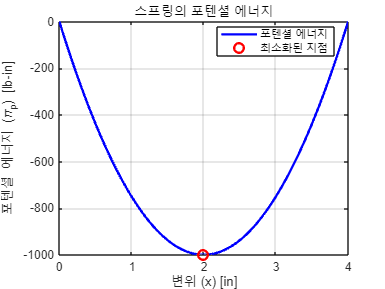


% 2D 포텐셜 에너지 그래프
x = linspace(0, 4, 100); % 변위 범위를 0에서 4인치까지 100개의 점으로 설정
F = 1000; % 고정된 외부 힘
pi_p = (1/2) * k * x.^2 - F * x;
x_min = F / k; % 평형 상태에서의 변위
pi_p_min = (1/2) * k * x_min^2 - F * x_min;

figure;
plot(x, pi_p, 'b-', 'LineWidth', 2); % 포텐셜 에너지 그래프
hold on;
plot(x_min, pi_p_min, 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 최소화된 지점 표시
xlabel('변위 (x) [in]');
ylabel('포텐셜 에너지 (\pi_p) [lb-in]');
title('스프링의 포텐셜 에너지');
legend('포텐셜 에너지', '최소화된 지점', 'Location', 'Best');
grid on;


% 결과 출력
fprintf('평형 상태에서의 변위: x_min = %.2f in\n', x_min);

평형 상태에서의 변위: x_min = 2.00 in


fprintf('평형 상태에서의 포텐셜 에너지: pi_p_min = %.2f lb-in\n', pi_p_min);

평형 상태에서의 포텐셜 에너지: pi_p_min = -1000.00 lb-in


**코드 설명**

- **입력 파라미터 설정:**

- 스프링 상수 $k = 500 lb/in$.

- 외부 힘 $F = 1000$lb.

- 변위 $x$의 범위를 0에서 4인치까지 설정.

- **포텐셜 에너지 계산:**

- 스프링 시스템의 전체 포텐셜 에너지는 $\pi_p = \frac{1}{2} k x^2 - F x\$로 계산합니다.

- 변위 $x$에 대해 포텐셜 에너지 값을 계산하여 벡터로 저장합니다.

- **포텐셜 에너지 최소화:**

- 최소화된 변위는 $x_{\text{min}} = \frac{F}{k}$로 계산합니다.

- 최소화된 변위에서의 포텐셜 에너지도 계산합니다.

% 스프링 상수 (k)와 외부 힘 (F) 정의
k = 500; % lb/in
F = 1000; % lb

% 변위 범위 설정
x_values = linspace(-4, 5, 10); % -4in에서 5in까지 10개의 점
pi_p_values = (1/2) * k * x_values.^2 - F * x_values; % 포텐셜 에너지 계산

% 데이터 표 출력
fprintf('Deformation (x), in\tTotal Potential Energy (pi_p), lb-in\n');

Deformation (x), in	Total Potential Energy (pi_p), lb-in


for i = 1:length(x_values)
    fprintf('%.2f\t\t\t\t\t%.2f\n', x_values(i), pi_p_values(i));
end

-4.00					8000.00
-3.00					5250.00
-2.00					3000.00
-1.00					1250.00
0.00					0.00
1.00					-750.00
2.00					-1000.00
3.00					-750.00
4.00					0.00
5.00					1250.00


위의 계산 식을 편미분을 한후 행렬식으로 계산하는 코드로 접근해보았지만

역행렬(비가역적 행렬)이기 때문에 계산이 불가하여 다시 수식으로 접근하였습니다.

- 전체 포텐셜 에너지 

$\pi_p$�: $\pi_p = \frac{1}{2} k (u_2 - u_1)^2 - f_{1x} u_1 - f_{2x} u_2$�

- 편미분을 사용하여 다음과 같은 식을 얻습니다: 


$$\frac{\partial \pi_p}{\partial u_1} = k(u_1 - u_2) - f_{1x} = 0$$



$$\frac{\partial \pi_p}{\partial u_2} = k(u_2 - u_1) - f_{2x} = 0$$


% 스프링 시스템의 파라미터 설정
k = 500; % 스프링 상수 (lb/in)
f1x = 1000; % 외부 힘 (F1) (lb)

% 변위 (u2) 범위 설정
u2_values = linspace(0, 3, 100); % 변위 u2의 범위 설정 (0부터 3인치까지)

% 전체 포텐셜 에너지 계산을 위한 배열 생성
pi_p_values = 0.5 * k * (u2_values).^2 - f1x * u2_values;

% 행렬 방정식을 풀어 변위 계산 (고정된 경계 조건)
K = [k]; % 스프링 강성 행렬
F = [f1x]; % 외부 힘 벡터
u2 = K \ F; % 변위 계산 (행렬 방정식 풀기)
u1 = 0; % 첫 번째 결점의 변위를 고정

% 최소화된 변위에 대한 포텐셜 에너지 계산
pi_p_min = 0.5 * k * (u2 - u1)^2 - f1x * u1;

% 결과 출력
fprintf('첫 번째 결점의 변위: u1 = %.4f in\n', u1);

첫 번째 결점의 변위: u1 = 0.0000 in


fprintf('두 번째 결점의 변위: u2 = %.4f in\n', u2);

두 번째 결점의 변위: u2 = 2.0000 in


fprintf('최소화된 포텐셜 에너지: pi_p_min = %.4f lb-in\n', pi_p_min);

최소화된 포텐셜 에너지: pi_p_min = 1000.0000 lb-in


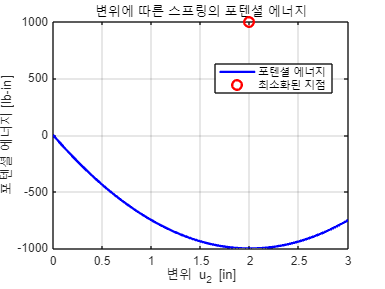


% 그래프 그리기
figure;
plot(u2_values, pi_p_values, 'b-', 'LineWidth', 2); % 포텐셜 에너지와 변위 그래프
hold on;
plot(u2, pi_p_min, 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 최소화된 지점 표시
xlabel('변위 u_2 [in]');
ylabel('포텐셜 에너지 [lb-in]');
title('변위에 따른 스프링의 포텐셜 에너지');
legend('포텐셜 에너지', '최소화된 지점', 'Location', 'Best');
grid on;

만약 행렬을 사용하여 접근한다면 아래와 같은 형식의 코드를 사용하면 된다.

% 스프링 시스템의 파라미터 설정
k = 500; % 스프링 상수 (lb/in)
f1x = 1000; % 외부 힘 (F1) (lb)
f2x = 0; % 외부 힘 (F2) (lb)

% 편미분 식에 의한 연립방정식 생성
% 행렬 [K] * [U] = [F]
K = [-k, k; k, -k]; % 스프링 강성 행렬
F = [f1x; f2x]; % 외부 힘 벡터

% 행렬 방정식을 풀어 변위 계산
U = K \ F; % 변위 계산 (행렬 방정식 풀기)

% 결과 추출
u1 = U(1); % 첫 번째 결점의 변위
u2 = U(2); % 두 번째 결점의 변위

% 최소화된 변위에 대한 포텐셜 에너지 계산
pi_p_min = 0.5 * k * (u2 - u1)^2 - f1x * u1 - f2x * u2;

% 결과 출력
fprintf('첫 번째 결점의 변위: u1 = %.4f in\n', u1);
fprintf('두 번째 결점의 변위: u2 = %.4f in\n', u2);
fprintf('최소화된 포텐셜 에너지: pi_p_min = %.4f lb-in\n', pi_p_min);
